frameCount = 1

frameCount = 2

frameCount = 3

frameCount = 4

frameCount = 5

frameCount = 6

frameCount = 7

frameCount = 8

frameCount = 9

frameCount = 10

frameCount = 11

frameCount = 12

frameCount = 13

frameCount = 14

frameCount = 15

frameCount = 16

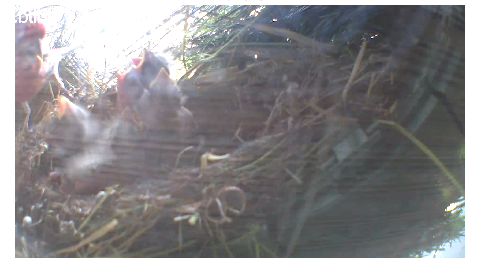

% Create a video reader object
v = VideoReader('G8V1900123_2024-05-08T14_38_23.mp4');

% Prepare a directory to save frames
framesDir = 'extracted_frames';
if ~exist(framesDir, 'dir')
    mkdir(framesDir);
end

% Initialize frame counter
frameCount = 0;

% Loop through video frames
while hasFrame(v)
    frame = readFrame(v);
    frameCount = frameCount + 1
    
    % Save frame as image
    frameFile = fullfile(framesDir, sprintf('frame_%d.png', frameCount));
    imwrite(frame, frameFile);
    
    % Display frame and pause for manual labeling (this can be enhanced with a GUI)
    imshow(frame);
    title(['Frame ', num2str(frameCount)]);
    pause; % Pause to view each frame - press any key to continue
end


% Note: Actual labeling interface needs to be more complex for data collection
